# Workflow DES + Agua

**1. Importar los datos de densidad**

Dens_Rel=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Dens_Reline","VariableNamingRule","preserve")

Dens_Rel = 304×10 table
         DES             Set Type           Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Density(kg.m-3)    Density(g.cm-3)        Reference         DES mole fraction
    _____________    ________________    _____________    __________________    ________________    ______________    _______________    _______________    __________________    _________________

    {'ChCl-Urea'}    {'Computed'    }    {'DES+Water'}              0                    1              303.15            1211.3             1.2113         {'(Celebi, 2019)'}           NaN       
    {'ChCl-Urea'}    {'Computed'    }    {'DES+

Gráfica de datos de densidad

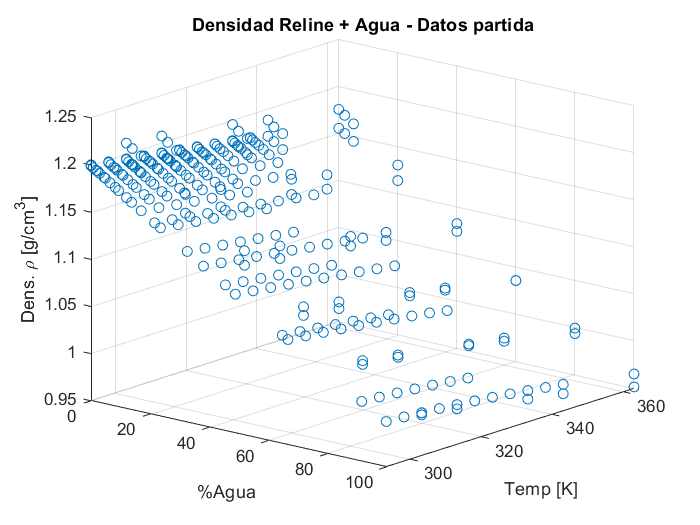

Masa_H2O_Rel=Dens_Rel.Mass_percent_Water*100;
Temp_Rel=Dens_Rel.("Temperature(K)");
Rho_Rel=Dens_Rel.("Density(g.cm-3)");
figure, plot3(Masa_H2O_Rel,Temp_Rel,Rho_Rel,'o');
title('Densidad Reline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento

data1=[Masa_H2O_Rel,Temp_Rel,Rho_Rel];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 304
       NumTestSets: 1
         TrainSize: 244
          TestSize: 60

Datos de entrenamiento

idx_train=training(particion);
train_data_dens1=data1(idx_train,:)

train_data_dens1 =          0  303.1500    1.2113
         0  313.1500    1.2069
         0  333.1500    1.1952
         0  343.1500    1.1880
         0  363.1500    1.1754
         0  303.1500    1.1945
         0  313.1500    1.1887
         0  333.1500    1.1773
         0  343.1500    1.1708
         0  363.1500    1.1554



Masa_H2O_Rel_train=train_data_dens1(:,1);
Temp_Rel_train=train_data_dens1(:,2);
Rho_Rel_train=train_data_dens1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_dens1=data1(idx_test,:)

test_data_dens1 =     2.0000  303.1500    1.2069
    2.0000  363.1500    1.1705
    2.0000  333.1500    1.1730
    2.0000  363.1500    1.1512
    5.0000  303.1500    1.1833
   20.0000  343.1500    1.1439
   20.0000  303.1500    1.1510
   20.0000  343.1500    1.1287
   40.0000  333.1500    1.1046
   40.0000  313.1500    1.1050



Masa_H2O_Rel_test=test_data_dens1(:,1);
Temp_Rel_test=test_data_dens1(:,2);
Rho_Rel_test=test_data_dens1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Rel_train Temp_Rel_train];
regresion1 = fitlm(predictores_train,Rho_Rel_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)         1.3512     0.0055779     242.25    8.3909e-290
    x1              -0.0020132    9.2217e-06    -218.31     5.814e-279
    x2             -0.00051778    1.7528e-05     -29.54     4.6318e-82


Number of observations: 244, Error degrees of freedom: 241
Root Mean Squared Error: 0.00482
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 2.45e+04, p-value = 3.86e-279

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación:')

Ecuación:

fprintf('Densidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Densidad= 1.3512+(-0.0020)*%Agua+(-0.0005)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Rel_train),max(Masa_H2O_Rel_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Rel_train),max(Temp_Rel_train))

Rango de temperatura: 293.15 K - 363.15 K

Ajuste del modelo

x1fit=min(Masa_H2O_Rel_train):2:max(Masa_H2O_Rel_train);
x2fit=min(Temp_Rel_train):1:max(Temp_Rel_train);
[X1fit,X2fit]=meshgrid(x1fit,x2fit);

Y1fit=coef1+coef2*X1fit+coef3*X2fit;




Gráfica 3D

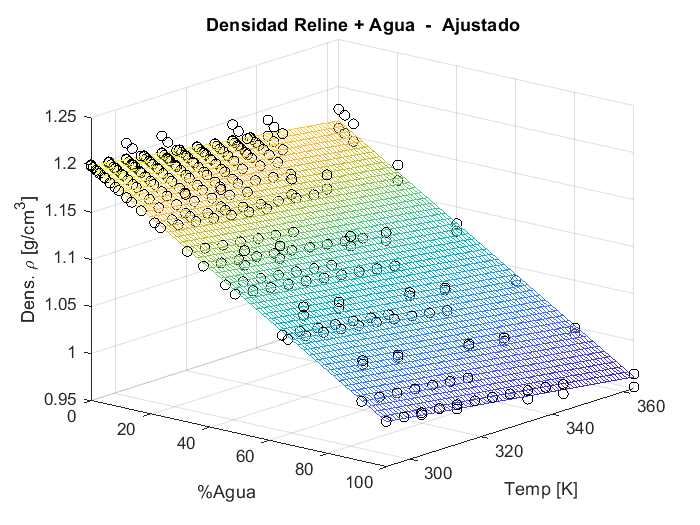

figure, plot3(Masa_H2O_Rel,Temp_Rel,Rho_Rel,'ok'); hold on,
mesh(X1fit,X2fit,Y1fit,'FaceAlpha','0.25'), hold off
title('Densidad Reline + Agua  -  Ajustado'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**4. Analisis de residuos del conjunto de entrenamiento**

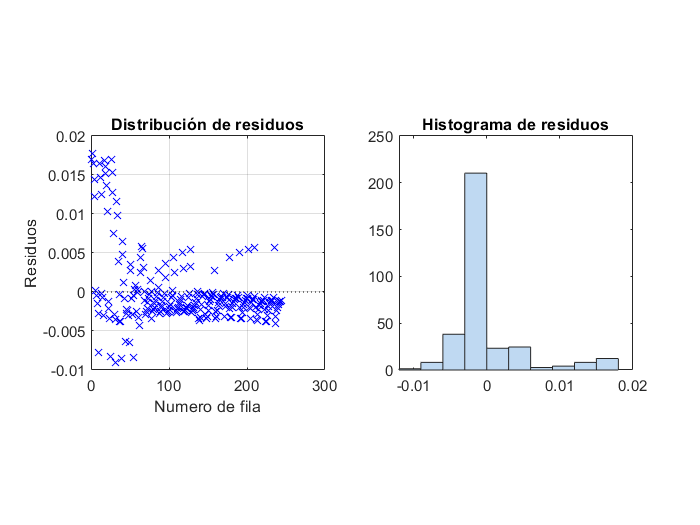

subplot(1,2,1)
plotResiduals(regresion1,'caseorder'),
title('Distribución de residuos'), xlabel('Numero de fila'),
ylabel('Residuos'), grid on, axis square
subplot(1,2,2)
plotResiduals(regresion1), title('Histograma de residuos'), axis square

El histograma muestra que los residuos están ligeramente sesgados a la derecha.

**5. Evaluación Datos de Prueba**

Grafica comparacion datos de prueba

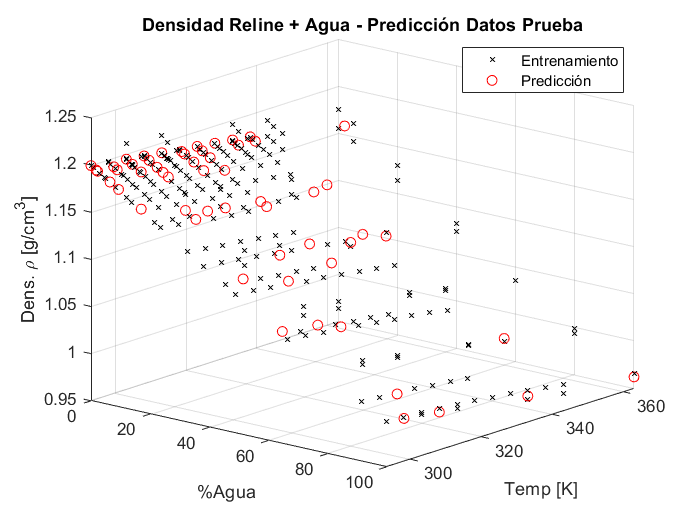

Y1_test=predict(regresion1,[Masa_H2O_Rel_test Temp_Rel_test]);
%Y1_test es la predicción con los datos de prueba
figure, plot3(Masa_H2O_Rel_train,Temp_Rel_train,Rho_Rel_train,'xk','MarkerSize',4)
hold on;
plot3(Masa_H2O_Rel_test,Temp_Rel_test,Y1_test,'or');
title('Densidad Reline + Agua - Predicción Datos Prueba'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
legend('Entrenamiento','Predicción',"Location","best")
view([40 20])

Graficas de residuos de los datos de prueba

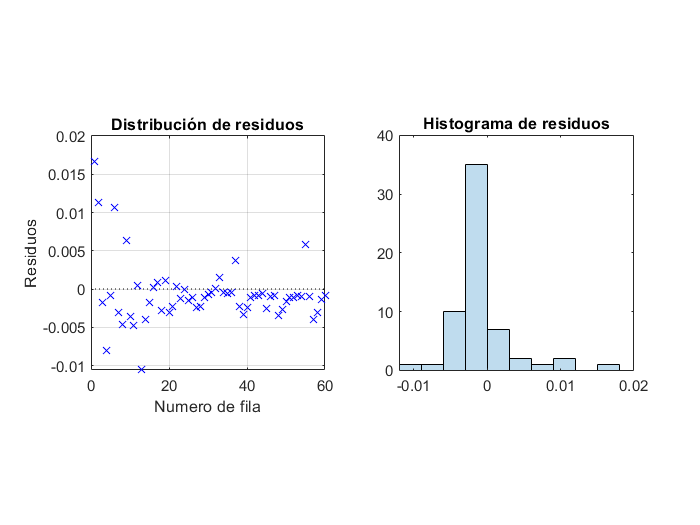

residuos_test=Rho_Rel_test-Y1_test;
subplot(1,2,1)
plot([0:length(Y1_test)],zeros*[0:length(Y1_test)],':k'), hold on,
plot(residuos_test,'xb'), title('Distribución de residuos'),
xlabel('Numero de fila'), ylabel('Residuos'),
grid on, hold off, axis square
subplot(1,2,2)
histogram(residuos_test,'FaceAlpha',0.25),
title('Histograma de residuos'), axis square